clear all, close all;

Detekcja ruchu SAD

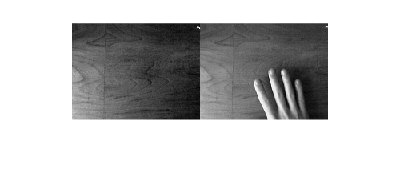

addpath("pliki_mov")
vidObj = VideoReader('motion1.avi');
im0 = read(vidObj, 1);
im1 = read(vidObj, 55);
im0gray = rgb2gray(im0);
im1gray = rgb2gray(im1);
imshowpair(im0gray, im1gray, 'montage')

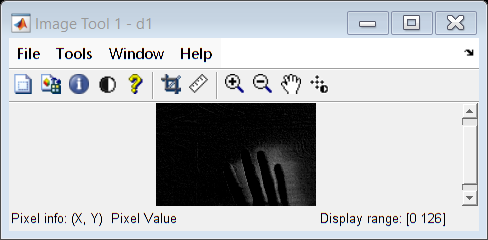


d1 = im0gray - im1gray;
imtool(d1, [])

[double(min(d1(:))) double(max(d1(:)))]

ans =      0   126



% wybieramy pixele o współrzędnych wiersz=70, kolumna=90
[im0gray(70,90) im1gray(70,90) d1(70,90)]

ans = 1×3 uint8 row vector
   109   208     0


class(im0gray)

ans = 'uint8'


d2 = double(im0gray) - double(im1gray);
[double(im0gray(70,90)) double(im1gray(70,90)) d2(70,90)]

ans =    109   208   -99


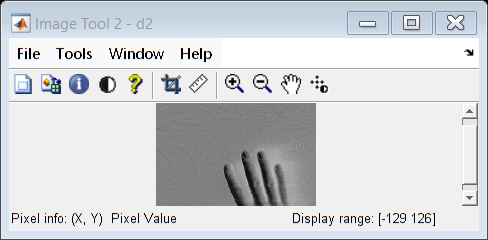

imtool(d2, [])

[double(min(d2(:))) double(max(d2(:)))]

ans =   -129   126



d3 = im2double(im0gray) - im2double(im1gray);
[im2double(im0gray(70,90)) im2double(im1gray(70,90)) d3(70,90)]

ans =     0.4275    0.8157   -0.3882


[double(min(d3(:))) double(max(d3(:)))]

ans =    -0.5059    0.4941



d4 = imabsdiff(im0gray, im1gray);
d4(70,90)

ans = uint8
99

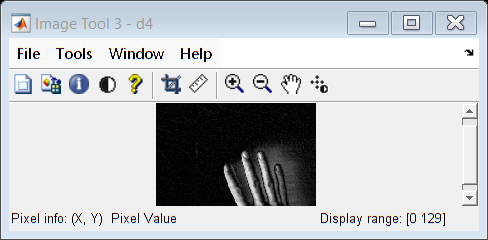

imtool(d4, [])

[double(min(d4(:))) double(max(d4(:)))]

ans =      0   129


---=== myDataSourceVid ===---
Dane źródła video:       
> nazwa pliku     = motion1.avi
> liczba ramek    = 223
> FPS             = 30
> rozdzielczość   = 120x160
> format koloru   = RGB24
---=== myAlgorithmSAD ===---
---=== myExportDataSAD ===---
Nazwa pliku wyjściowego TXT  =       movout.txt
---=== myVisualizationSAD ===---
Początek przetwarzania


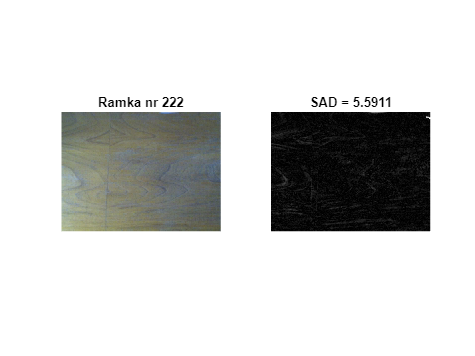

Zakończenie przetwarzania - obiekty usunięte


testHarness_SAD

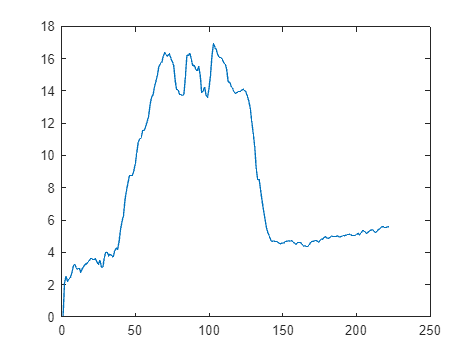

T = readtable('movout.txt'); % wczytanie danych z pliku txt jako typ danych Table
figure;
plot(T.sad);

Detekcja ruchu MHI

testHarness_MHI

---=== myDataSourceVid ===---
Dane źródła video:       
> nazwa pliku     = motion1.avi
> liczba ramek    = 223
> FPS             = 30
> rozdzielczość   = 120x160
> format koloru   = RGB24
---=== myAlgorithmMHI ===---
---=== myExportData ===---
Nazwa pliku wyjściowego TXT  =       tmp.txt
---=== myVisualizationMHI ===---
Początek przetwarzania


Detekcja ruchu OF

---=== myDataSourceVid ===---
Dane źródła video:       
> nazwa pliku     = motion1.avi
> liczba ramek    = 223
> FPS             = 30
> rozdzielczość   = 120x160
> format koloru   = RGB24
---=== myAlgorithmOF ===---
---=== myExportData ===---
Nazwa pliku wyjściowego TXT  =       tmp.txt
---=== myVisualizationOF ===---
Początek przetwarzania


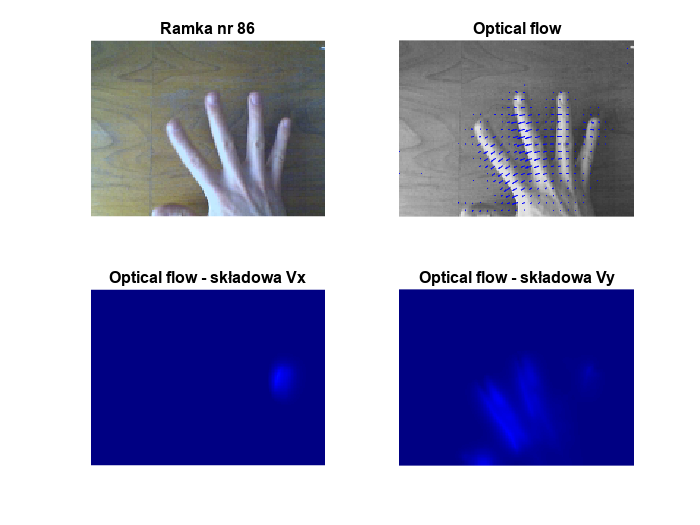

testHarness_OF